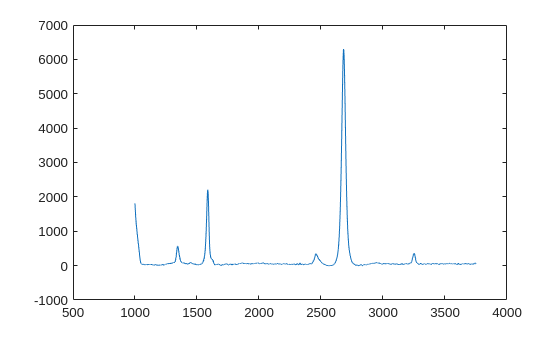

graphene2_data = readmatrix('Graphene2_1000to3750_nobase.txt');

% Extract relevant columns from the data
wavenumber = graphene2_data(:, 1);
count = graphene2_data(:, 2);

%plot
plot(wavenumber,count)

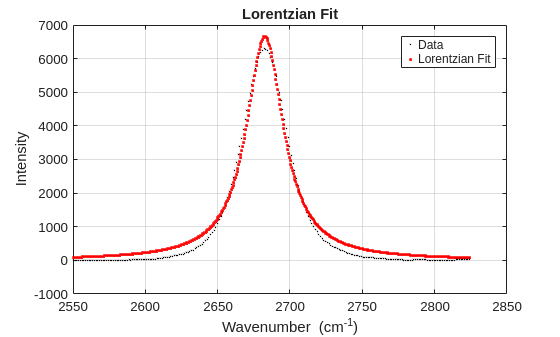

idx = wavenumber >= 2550 & wavenumber <= 2825;
wn_fit = wavenumber(idx);
int_fit = count(idx);

% Fit with a single Lorentzian (peak)
ft = fittype('a1/(1+((x-b1)/c1)^2)', 'independent', 'x');
[fitresult, gof] = fit(wn_fit, int_fit, ft, 'StartPoint', [max(int_fit), 2687, 50]);

% Plot with custom styling
figure;
plot(wn_fit, int_fit, '.k', 'MarkerSize', 2, 'DisplayName', 'Data');
hold on;

% Generate smooth line for the fit
x_smooth = linspace(min(wn_fit), max(wn_fit), 500);
y_smooth = fitresult(x_smooth);
plot(x_smooth, y_smooth, 'r.', 'LineWidth', 2, 'DisplayName', 'Lorentzian Fit');

xlabel('Wavenumber (cm^{-1})');
ylabel('Intensity');
title('Lorentzian Fit');
legend('show');
grid on;
hold off;


% Display results
fitresult

fitresult =      General model:
     fitresult(x) = a1/(1+((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =        6653  (6524, 6782)
       b1 =        2683  (2682, 2683)
       c1 =       15.69  (15.26, 16.12)

gof

gof = struct with fields:
           sse: 1.0206e+07
       rsquare: 0.9855
           dfe: 229
    adjrsquare: 0.9853
          rmse: 211.1104
